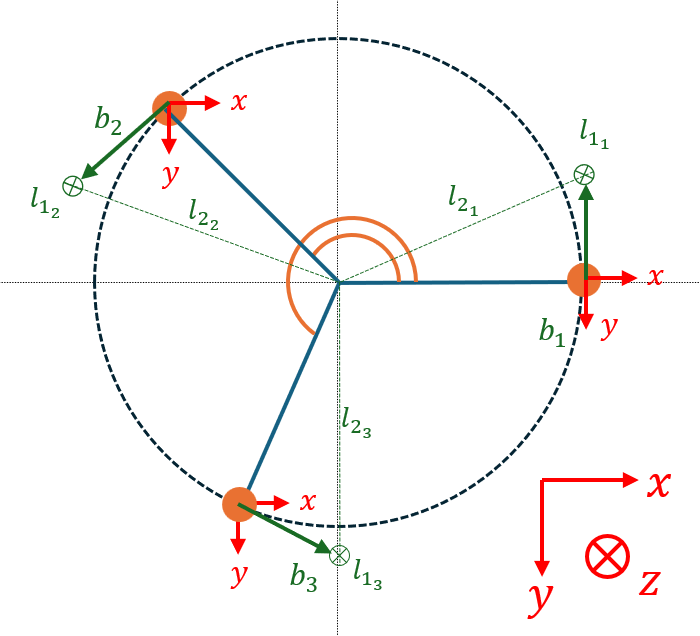

clc
clear
syms b r theta_1 theta_2 theta_3 real
syms S B [3 3]
syms s_1 s_2 s_3 [3 1]
syms r_s r_p positive real
syms Q [3 3]
r_val = 0.05;
r_s_val = 0.020;
r_p_val = 0.032;
b_val = 0.003;

clear pi
gamma = 2*pi/3;
angles = [0, gamma, 2*gamma];
theta = [theta_1 ; theta_2 ; theta_3];
S = [s_1 , s_2 , s_3];
for i = 1:3
    servo_angle = angles(i);
    S(:,i) = [r*cos(servo_angle); r*sin(servo_angle); 0];  % point on circle in xy-plane
end
S

$$S = \left(\begin{array}{ccc} r & -\frac{r}{2} & -\frac{r}{2}\\ 0 & \frac{\sqrt{3}\,r}{2} & -\frac{\sqrt{3}\,r}{2}\\ 0 & 0 & 0 \end{array}\right)$$

Derriving Q


servo_tips = [ r_s .* cos(theta) , r_s .* sin(theta) ]'

$$servo\_tips = \left(\begin{array}{ccc} r_{s}\,\cos\left(\theta_{1}\right) & r_{s}\,\cos\left(\theta_{2}\right) & r_{s}\,\cos\left(\theta_{3}\right)\\ r_{s}\,\sin\left(\theta_{1}\right) & r_{s}\,\sin\left(\theta_{2}\right) & r_{s}\,\sin\left(\theta_{3}\right) \end{array}\right)$$

norms = simplify(sqrt(sum(S.^2, 1)));
n = simplify(S ./ norms);
% 1) build two in‐plane basis vectors (u tangent to the circle, v = n×u)
u = [-S(2,:); 
      S(1,:); 
      zeros(1,3)];               % a vector tangent to the circle in xy
u = u ./ sqrt(sum(u.^2,1));     % normalize each column

v = cross(n, u, 1);             % second in-plane axis, also normalized

% 2) map your 2×3 servo_tips = [u_i; v_i] into a 3×3 delta per plane
%    servo_tips(1,i) = u_i , servo_tips(2,i) = v_i
delta = u .* servo_tips(1,:) + v .* servo_tips(2,:);

% 3) the 3D endpoints of the servo-horns on each plane
Q = simplify(S + delta)

$$Q = \left(\begin{array}{ccc} r & -\frac{r\,\left(\left|r\right|+\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)\right)}{2\,\left|r\right|} & -\frac{r\,\left(\left|r\right|-\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)\right)}{2\,\left|r\right|}\\ \frac{r\,r_{s}\,\cos\left(\theta_{1}\right)}{\left|r\right|} & \frac{r\,\left(\sqrt{3}\,\left|r\right|-r_{s}\,\cos\left(\theta_{2}\right)\right)}{2\,\left|r\right|} & -\frac{r\,\left(\sqrt{3}\,\left|r\right|+r_{s}\,\cos\left(\theta_{3}\right)\right)}{2\,\left|r\right|}\\ r_{s}\,\sin\left(\theta_{1}\right) & r_{s}\,\sin\left(\theta_{2}\right) & r_{s}\,\sin\left(\theta_{3}\right) \end{array}\right)$$

Sanity check to make sure Q was derrived accurately

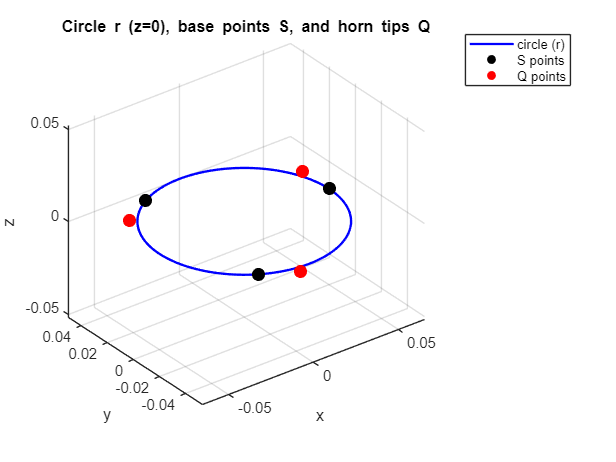

%% === PLOT:  circle (r), points S, points Q ============================

% ---- numeric values you want to visualise -----------------------------
r_plot     = r_val;              % 0.05   – base-circle radius
rs_plot    = r_s_val;            % 0.020  – horn radius
theta_plot = [0; 0; 0];          % servo angles (rad) – change as needed

% ---- evaluate the symbolic S and Q numerically ------------------------
S_plot = double( subs(S, r, r_plot) );                         % 3×3
Q_plot = double( subs(Q, [r, r_s, theta_1,theta_2,theta_3], ...
                        [r_plot, rs_plot, theta_plot.']) );    % 3×3

% ---- base circle in z = 0 --------------------------------------------
tt  = linspace(0, 2*pi, 400);
xc  = r_plot * cos(tt);
yc  = r_plot * sin(tt);
zc  = zeros(size(tt));

% ==================   P L O T   ========================================
figure;  hold on;  axis equal;  view(3);  grid on;
xlabel('x');  ylabel('y');  zlabel('z');
title('Circle r (z{=}0), base points S, and horn tips Q');

% 1) circle
plot3(xc, yc, zc, 'b-', 'LineWidth', 1.6, 'DisplayName', 'circle (r)');

% 2) points S (black)
scatter3(S_plot(1,:), S_plot(2,:), S_plot(3,:), ...
         80, 'ko', 'filled', 'DisplayName', 'S points');

% 3) points Q (red)
scatter3(Q_plot(1,:), Q_plot(2,:), Q_plot(3,:), ...
         80, 'ro', 'filled', 'DisplayName', 'Q points');

legend('Location','bestoutside');
hold off;

% circle_eq = x^2 + y^2 == r^2
% Loop version:
for i = 1:size(S,2)
    % Extract the point on the circle
    x0 = S(1,i);
    y0 = S(2,i);
    
    % Tangent direction (perp. to radius)
    v = [ -y0; 
           x0; 
            0 ];
    
    % Normalize to unit length
    B(:,i) = v / norm(v);
end

% Now B(:,i) is the unit‐tangent vector at S(:,i).

% --- Or, in one vectorized line: ---
V = [ -S(2,:);   % -y0
       S(1,:);   %  x0
      zeros(1,3) ];
B = V / r     % since ‖V(:,i)‖ = sqrt(y0^2 + x0^2) = r

$$B = \left(\begin{array}{ccc} 0 & -\frac{\sqrt{3}}{2} & \frac{\sqrt{3}}{2}\\ 1 & -\frac{1}{2} & -\frac{1}{2}\\ 0 & 0 & 0 \end{array}\right)$$

% Given values
r_tmp = r_val;   % e.g., 1
b_tmp = b_val;   % e.g., 1

% Define the three sample points S on the circle
gamma_tmp  = 2*pi/3;
angles_tmp = [0, gamma, 2*gamma];
S_tmp = [ r_tmp*cos(angles);
      r_tmp*sin(angles);
      zeros(1,3) ];

% Compute unit‐tangent vectors B at each S(:,i)
V = [ -S_tmp(2,:);    % -y0
       S_tmp(1,:);    %  x0
       zeros(1,3)];
B_tmp = V ./ r_tmp;      % since norm([−y0; x0]) = r

% Prepare circle for plotting
theta_tmp = linspace(0, 2*pi, 360);
xc = r_tmp*cos(theta_tmp);
yc = r_tmp*sin(theta_tmp);

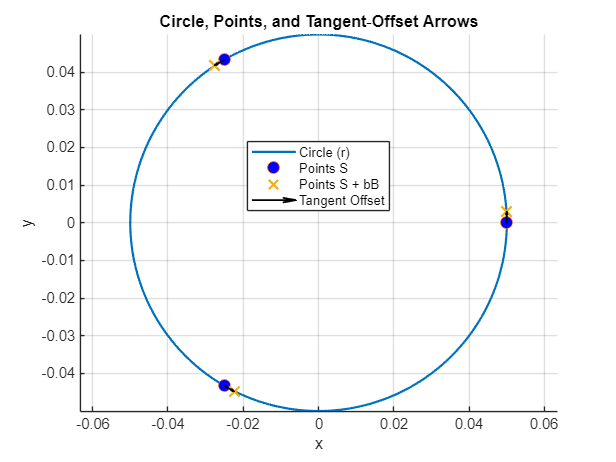

% Plot everything
figure; hold on; axis equal

% 1) the circle
plot(xc, yc, 'LineWidth', 1.5, 'DisplayName', 'Circle (r)');

% 2) the points S
plot(S_tmp(1,:), S_tmp(2,:), 'o', 'MarkerSize', 8, 'MarkerFaceColor','b', 'DisplayName', 'Points S');

% 3) the offset points S + b * B
Sp = S_tmp + b_tmp * B_tmp;
plot(Sp(1,:), Sp(2,:), 'x', 'MarkerSize', 10, 'LineWidth', 1.5, 'DisplayName', 'Points S + bB');

% 4) arrows from S to S + b*B
%    use quiver with scale 0 so vectors are not auto‐scaled
quiver( ...
    S_tmp(1,:), S_tmp(2,:), ...         % arrow starting points
    b_tmp*B_tmp(1,:), b_tmp*B_tmp(2,:), ...     % arrow directions
    0, ...                      % no auto-scaling
    'k', 'LineWidth', 1.2, ...  % black arrows
    'MaxHeadSize', 0.5, ...
    'DisplayName', 'Tangent Offset' ...
);

% Enhance plot
xlabel('x'); ylabel('y');
legend('Location','best');
title('Circle, Points, and Tangent‐Offset Arrows');
grid on; hold off


%Right L is the lines, we now replace the bottom rows with free variables
%so that 
syms l_1 l_2 l_3 real
L = S + b * B;
L = L + [0, 0, 0 ; 0, 0, 0 ; l_1 , l_2 , l_3] 

$$L = \left(\begin{array}{ccc} r & -\frac{r}{2}-\frac{\sqrt{3}\,b}{2} & \frac{\sqrt{3}\,b}{2}-\frac{r}{2}\\ b & \frac{\sqrt{3}\,r}{2}-\frac{b}{2} & -\frac{b}{2}-\frac{\sqrt{3}\,r}{2}\\ l_{1} & l_{2} & l_{3} \end{array}\right)$$

L now is the first line to form our plane, the 2nd line is 

syms P [3 4]
S

$$S = \left(\begin{array}{ccc} r & -\frac{r}{2} & -\frac{r}{2}\\ 0 & \frac{\sqrt{3}\,r}{2} & -\frac{\sqrt{3}\,r}{2}\\ 0 & 0 & 0 \end{array}\right)$$

for i = 1:3
  % the point in the z=0 plane
  PL     = S(:,i) + b*B(:,i);

  % normal of the vertical plane through PL and the z‐axis
  n3     = cross( PL, [0;0;1] );   % = [ PL(2); -PL(1); 0 ]
  n2row  = n3(1:2).';               % 1×2

  % force the plane to pass through PL => A*PLx + B*PLy + D = 0
  D      = - ( n2row * PL(1:2) );

  % store [A, B, C, D]
  P(i,:) = [ n2row, 0, D ];
end
P

$$P = \left(\begin{array}{cccc} b & -r & 0 & 0\\ \frac{\sqrt{3}\,r}{2}-\frac{b}{2} & \frac{r}{2}+\frac{\sqrt{3}\,b}{2} & 0 & 0\\ -\frac{b}{2}-\frac{\sqrt{3}\,r}{2} & \frac{r}{2}-\frac{\sqrt{3}\,b}{2} & 0 & 0 \end{array}\right)$$

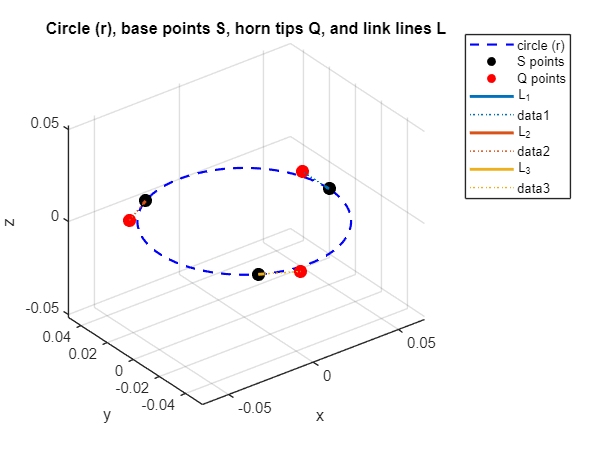

%% === COMBINED PLOT :  Circle (r), points S, points Q, and lines L ======

% ----- numeric values you want to visualise -----------------------------
r_plot   = r_val;                 % 0.05
b_plot   = b_val;                 % 0.003
rs_plot  = r_s_val;               % 0.020
theta_pl = [0; 0; 0];             % ↙︎ servo angles (rad) – set as needed

% ----- evaluate symbolic expressions numerically ------------------------
S_plot = double( subs(S, r, r_plot) );                       % 3×3
B_plot = double( subs(B, r, r_plot) );                       % 3×3
Q_plot = double( subs(Q, [r, r_s, theta_1,theta_2,theta_3],  ...
                        [r_plot,rs_plot,theta_pl.']) );      % 3×3
L_plot = S_plot + b_plot * B_plot;                           % 3×3

% ----- reference circle in the z = 0 plane ------------------------------
th  = linspace(0,2*pi,400);
xc  = r_plot*cos(th);        yc  = r_plot*sin(th);   zc = zeros(size(th));

% ==================   P L O T   =========================================
figure;  hold on;  axis equal;  view(3);  grid on;
xlabel('x');  ylabel('y');  zlabel('z');
title('Circle (r), base points S, horn tips Q, and link lines L');

% 1) circle
plot3(xc,yc,zc,'b--','LineWidth',1.5,'DisplayName','circle (r)');

% 2) points S
scatter3(S_plot(1,:),S_plot(2,:),S_plot(3,:), ...
         80,'ko','filled','DisplayName','S points');

% 3) points Q
scatter3(Q_plot(1,:),Q_plot(2,:),Q_plot(3,:), ...
         80,'ro','filled','DisplayName','Q points');

% 4) link lines L  (S → L, plus dotted vertical up to Q)
cols = lines(3);   % nice distinct colours
for k = 1:3
    % main line S → L
    plot3([S_plot(1,k), L_plot(1,k)], ...
          [S_plot(2,k), L_plot(2,k)], ...
          [S_plot(3,k), L_plot(3,k)], ...
          'LineWidth',2,'Color',cols(k,:), ...
          'DisplayName',sprintf('L_%d',k));
    
    % (optional) dotted guideline from L up/down to Q for visual context
    plot3([L_plot(1,k), Q_plot(1,k)], ...
          [L_plot(2,k), Q_plot(2,k)], ...
          [L_plot(3,k), Q_plot(3,k)], ...
          ':','LineWidth',1,'Color',cols(k,:));
end

legend('Location','bestoutside');
hold off;

Ok these planes are the ranges of motion for the swash plate. Now it is time to actually derrive the equations. We input points Q onto this graph,which are the tips of the servo horns

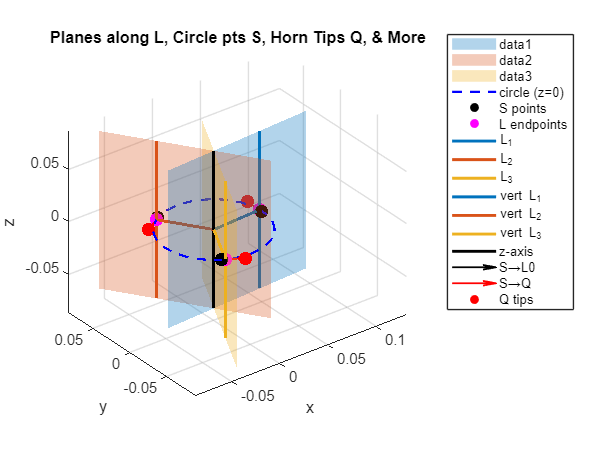




%% --- NUMERIC CONVERSION FOR PLOTTING ---
r_plot  = r_val;
b_plot  = b_val;
rs_plot = r_s_val;           % your rs_value
theta_plot = [0;0;0];    % your theta_value

% numeric S, B, and Q
S_plot = double( subs(S,   r,   r_plot) );         % 3×3
B_plot = double( subs(B,   r,   r_plot) );         % 3×3
Q_plot = double( subs(Q,   [r,r_s,theta_1,theta_2,theta_3], ...
                      [r_plot,rs_plot,theta_plot.']) );

% compute L0 = S + b*B
L0 = S_plot + b_plot * B_plot;   % 3×3

%% --- PLOTTING ALL ON ONE 3D AXES ---
figure; hold on; axis equal; view(3); grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title('Planes along L, Circle pts S, Horn Tips Q, & More');

% 1) vertical planes spanned by L0(:,k) & z‐axis
L_patch = 1.5 * r_plot;
cols    = lines(3);
for k = 1:3
    lv = L0(:,k);
    n3 = cross(lv, [0;0;1]);
    Bplane = null(n3.');
    u_p = Bplane(:,1); v_p = Bplane(:,2);
    pc = lv/2;
    verts = [ pc + L_patch*( u_p+ v_p ), ...
              pc + L_patch*( u_p- v_p ), ...
              pc + L_patch*(-u_p- v_p ), ...
              pc + L_patch*(-u_p+ v_p ) ];
    patch('Vertices', verts.', 'Faces',[1 2 3 4], ...
          'FaceColor',cols(k,:), 'FaceAlpha',0.3, 'EdgeColor','none');
end

% 2) circle in z=0
th = linspace(0,2*pi,360);
plot3(r_plot*cos(th), r_plot*sin(th), zeros(size(th)), ...
      'b--','LineWidth',1.5, 'DisplayName','circle (z=0)');

% 3) points S and L0 endpoints
scatter3(S_plot(1,:), S_plot(2,:), S_plot(3,:), 80, 'ko','filled', 'DisplayName','S points');
scatter3(L0(1,:), L0(2,:), L0(3,:),    80, 'mo','filled', 'DisplayName','L endpoints');

% 4) L‐vectors in z=0
for k=1:3
  plot3([0,L0(1,k)], [0,L0(2,k)], [0,0], '-', ...
        'Color',cols(k,:), 'LineWidth',2, 'DisplayName',sprintf('L_%d',k));
end

% 5) vertical lines at L0(:,k)
zlim_vals = 1.5*r_plot * [-1 1];
for k=1:3
  plot3([L0(1,k),L0(1,k)], [L0(2,k),L0(2,k)], zlim_vals, '-', ...
        'Color',cols(k,:), 'LineWidth',2, 'DisplayName',sprintf('vert L_%d',k));
end

% 6) z‐axis
plot3([0 0],[0 0],zlim_vals, 'k-','LineWidth',2,'DisplayName','z-axis');

% 7) arrows S→L0
quiver3( S_plot(1,:),S_plot(2,:),S_plot(3,:), ...
         L0(1,:)-S_plot(1,:), L0(2,:)-S_plot(2,:), zeros(1,3), ...
         0,'k','LineWidth',1.2,'MaxHeadSize',0.5, 'DisplayName','S→L0');

% 8) horn‐tip arrows S→Q and Q points
quiver3( S_plot(1,:),S_plot(2,:),S_plot(3,:), ...
         Q_plot(1,:)-S_plot(1,:), Q_plot(2,:)-S_plot(2,:), Q_plot(3,:)-S_plot(3,:), ...
         0,'r','LineWidth',1.2,'MaxHeadSize',0.5, 'DisplayName','S→Q');
scatter3(Q_plot(1,:), Q_plot(2,:), Q_plot(3,:), 80, 'r','filled', 'DisplayName','Q tips');

% finalize legend (remove duplicates)
lh = legend('Location','bestoutside');
[~, idx] = unique(lh.String);
lh.String = lh.String(sort(idx));

hold off;

Q

$$Q = \left(\begin{array}{ccc} r & -\frac{r\,\left(\left|r\right|+\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)\right)}{2\,\left|r\right|} & -\frac{r\,\left(\left|r\right|-\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)\right)}{2\,\left|r\right|}\\ \frac{r\,r_{s}\,\cos\left(\theta_{1}\right)}{\left|r\right|} & \frac{r\,\left(\sqrt{3}\,\left|r\right|-r_{s}\,\cos\left(\theta_{2}\right)\right)}{2\,\left|r\right|} & -\frac{r\,\left(\sqrt{3}\,\left|r\right|+r_{s}\,\cos\left(\theta_{3}\right)\right)}{2\,\left|r\right|}\\ r_{s}\,\sin\left(\theta_{1}\right) & r_{s}\,\sin\left(\theta_{2}\right) & r_{s}\,\sin\left(\theta_{3}\right) \end{array}\right)$$

Plot the point on the line that connects to Q by exactly r_p

Derrivation

%% 6) Solve symbolically for P_sym on each vertical line:
%    ≥P_i–Q_i‖ = r_p, choose P below Q
d_xy    = sqrt( (L0(1,:)-Q(1,:)).^2 + (L0(2,:)-Q(2,:)).^2 );
dz_sym  =        sqrt( r_p^2 - d_xy.^2 );
P_sym   = [ L0(1,:)       ;
            L0(2,:)       ;
            Q(3,:) - dz_sym ];

%% 7) Plane through P1,P2,P3  ⇒  A x + Bp y + C z + D = 0
P1 = P_sym(:,1);  P2 = P_sym(:,2);  P3 = P_sym(:,3);
v1 = P2 - P1;     v2 = P3 - P1;
n_plane = simplify( cross(v1, v2, 1) );  % [A; Bp; C]
A       = n_plane(1);
Bp      = n_plane(2);
C       = n_plane(3);
D       = simplify( - (n_plane.' * P1) );

%% 8) Generalized coordinates (coupled functions of all θ_i)
heave   = simplify( -D / C );         % vertical offset
pitch_x = simplify( atan( -Bp / C ) ); % rotation about x
roll_y  = simplify( atan( -A  / C ) ); % rotation about y

X_sym = [ heave;
          pitch_x;
          roll_y ];

U_sym = [ theta_1;
          theta_2;
          theta_3 ];


## 9) Display the coupling

X_approx = vpa( simplify(X_sym), 6 )

$$X\_approx = \begin{array}{l} \left(\begin{array}{c} 0.333333\,r_{s}\,\sin\left(\theta_{1}\right)-0.333333\,\sigma_{2}+0.333333\,r_{s}\,\sin\left(\theta_{2}\right)+0.333333\,r_{s}\,\sin\left(\theta_{3}\right)-0.333333\,\sigma_{1}-0.333333\,\sigma_{3}\\ \mathrm{atan}\left(11.9042\,\sigma_{2}+0.79713\,r_{s}\,\sin\left(\theta_{1}\right)+11.107\,r_{s}\,\sin\left(\theta_{2}\right)-11.9042\,r_{s}\,\sin\left(\theta_{3}\right)-11.107\,\sigma_{1}-0.79713\,\sigma_{3}\right)\\ \mathrm{atan}\left(5.95242\,\sigma_{2}+13.2855\,r_{s}\,\sin\left(\theta_{1}\right)-7.33309\,r_{s}\,\sin\left(\theta_{2}\right)-5.95242\,r_{s}\,\sin\left(\theta_{3}\right)+7.33309\,\sigma_{1}-13.2855\,\sigma_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{r_{p}}^{2}-1.0\,{\left(\frac{0.5\,r\,\left(\left|r\right|+1.73205\,r_{s}\,\cos\left(\theta_{2}\right)\right)}{\left|r\right|}-0.0275981\right)}^{2}-1.0\,{\left(\frac{0.5\,r\,\left(1.73205\,\left|r\right|-1.0\,r_{s}\,\cos\left(\theta_{2}\right)\right)}{\left|r\right|}-0.0418013\right)}^{2}}\\ \sigma_{2}=\sqrt{{r_{p}}^{2}-1.0\,{\left(\frac{0.5\,r\,\left(\left|r\right|-1.73205\,r_{s}\,\cos\left(\theta_{3}\right)\right)}{\left|r\right|}-0.0224019\right)}^{2}-1.0\,{\left(\frac{0.5\,r\,\left(1.73205\,\left|r\right|+r_{s}\,\cos\left(\theta_{3}\right)\right)}{\left|r\right|}-0.0448013\right)}^{2}}\\ \sigma_{3}=\sqrt{{r_{p}}^{2}-1.0\,{\left(r-0.05\right)}^{2}-1.0\,{\left(\frac{r\,r_{s}\,\cos\left(\theta_{1}\right)}{\left|r\right|}-0.003\right)}^{2}} \end{array}$$

% disp('Mapping X = [heave; pitch_x; roll_y] as functions of all three θ:');
% for k = 1:3
%     fprintf('  X(%d) = %s\n', k, char(X_sym(k)));
% end












Other derrivations

% compute horizontal distance per column
d_xy_sym = sqrt( (L(1,:) - Q(1,:)).^2 + (L(2,:) - Q(2,:)).^2 );

% vertical offset => two roots ±, take negative (P below Q)
dz_sym    =        sqrt( r_p^2 - d_xy_sym.^2 );

% build the symbolic P matrix
P_sym = [ ...
    L(1,:)         ;    % x = same as L
    L(2,:)         ;    % y = same as L
    Q(3,:) - dz_sym   % z = Qz - dz
    ];

P_sym = simplify(P_sym)

$$P\_sym = \begin{array}{l} \left(\begin{array}{ccc} r & -\frac{r}{2}-\sigma_{2} & \sigma_{2}-\frac{r}{2}\\ b & \sigma_{1}-\frac{b}{2} & -\frac{b}{2}-\sigma_{1}\\ r_{s}\,\sin\left(\theta_{1}\right)-\sqrt{{r_{p}}^{2}-{\left(b-\frac{r\,r_{s}\,\cos\left(\theta_{1}\right)}{\left|r\right|}\right)}^{2}} & r_{s}\,\sin\left(\theta_{2}\right)-\frac{\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{2}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\right)}}{\left|r\right|} & r_{s}\,\sin\left(\theta_{3}\right)-\frac{\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{3}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\right)}}{\left|r\right|} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,r}{2}\\ \sigma_{2}=\frac{\sqrt{3}\,b}{2} \end{array}$$


%% --- Compute P_plot so that ‖P_i–Q_i‖ = r_p   (P below Q) ---
rp_plot = r_p_val;              % e.g. 0.032
P_plot = zeros(3,3);

for i = 1:3
    % horizontal (xy) distance from line-base to Q
    d_xy = norm( L0(1:2,i) - Q_plot(1:2,i) );
    % vertical offset = sqrt(r_p^2 - d_xy^2)
    dz   = sqrt( rp_plot^2 - d_xy^2 );
    % pick P beneath Q
    P_plot(:,i) = [ L0(1,i);
                    L0(2,i);
                    Q_plot(3,i) - dz ];
end


Plot

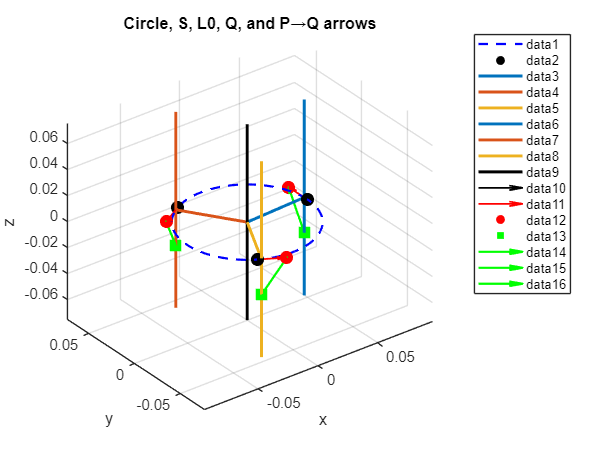

%% --- Now do the 3D plot (no planes) ---
figure; hold on; axis equal; view(3); grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title('Circle, S, L0, Q, and P→Q arrows');

% circle in z=0
th = linspace(0,2*pi,400);
plot3(r_plot*cos(th), r_plot*sin(th), zeros(size(th)), 'b--', 'LineWidth',1.5);

% points S (black) and L0 (magenta)
scatter3(S_plot(1,:), S_plot(2,:), S_plot(3,:), 80, 'ko','filled');
% scatter3(L0(1,:), L0(2,:), L0(3,:),    80, 'mo','filled');

% L0 vectors in plane
cols = lines(3);
for k = 1:3
    plot3([0,L0(1,k)], [0,L0(2,k)], [0,0], '-', 'LineWidth',2, 'Color',cols(k,:));
end

% vertical lines at each L0
zlim_vals = 1.5*r_plot * [-1 1];
for k = 1:3
    plot3([L0(1,k),L0(1,k)], [L0(2,k),L0(2,k)], zlim_vals, '-', 'LineWidth',2, 'Color',cols(k,:));
end

% z‐axis
plot3([0 0],[0 0],zlim_vals, 'k-','LineWidth',2);

% arrows S→L0
quiver3( S_plot(1,:),S_plot(2,:),S_plot(3,:), ...
         L0(1,:)-S_plot(1,:), L0(2,:)-S_plot(2,:), zeros(1,3), ...
         0,'k','LineWidth',1.2,'MaxHeadSize',0.5);

% arrows S→Q & Q points (red)
quiver3( S_plot(1,:),S_plot(2,:),S_plot(3,:), ...
         Q_plot(1,:)-S_plot(1,:), Q_plot(2,:)-S_plot(2,:), Q_plot(3,:)-S_plot(3,:), ...
         0,'r','LineWidth',1.2,'MaxHeadSize',0.5);
scatter3(Q_plot(1,:), Q_plot(2,:), Q_plot(3,:), 80, 'r','filled');

% P points on L (green squares)
scatter3( P_plot(1,:), P_plot(2,:), P_plot(3,:), ...
          100, 'gs', 'filled');

% arrows P→Q (green)
for i = 1:3
    quiver3( P_plot(1,i),P_plot(2,i),P_plot(3,i), ...
             Q_plot(1,i)-P_plot(1,i), ...
             Q_plot(2,i)-P_plot(2,i), ...
             Q_plot(3,i)-P_plot(3,i), ...
             0,'g','LineWidth',1.5,'MaxHeadSize',0.5);
end

legend('Location','bestoutside');
hold off;



% --- extract the three P points ---
P1 = P_plot(:,1);
P2 = P_plot(:,2);
P3 = P_plot(:,3);

% --- two in‐plane vectors and normal ---
v1 = P2 - P1;
v2 = P3 - P1;
n  = cross(v1, v2);        % normal vector [A; B; C]

A = n(1);
B = n(2);
C = n(3);

% --- solve for D so that A*x1 + B*y1 + C*z1 + D = 0 ---
D = - (n.' * P1);

fprintf('Plane: %g x + %g y + %g z + %g = 0\n', A, B, C, D);

Plane: 0 x + 0 y + 0.00651857 z + 0.000176724 = 0


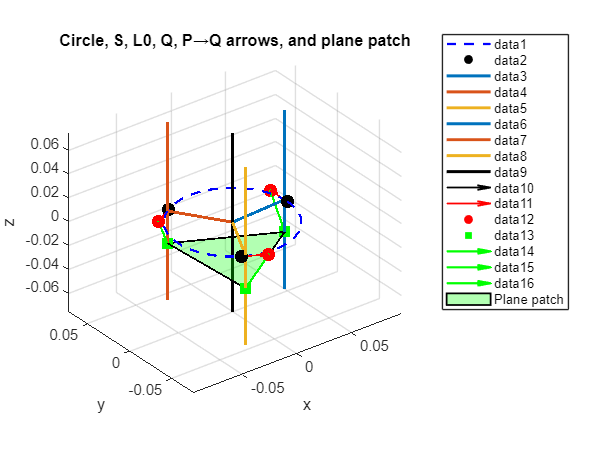

%% --- Combined 3D plot with triangular plane patch ---

figure;
hold on; axis equal; view(3); grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title('Circle, S, L0, Q, P→Q arrows, and plane patch');

% 1) circle in z=0
th = linspace(0,2*pi,400);
plot3(r_plot*cos(th), r_plot*sin(th), zeros(size(th)), 'b--', 'LineWidth',1.5);

% 2) points S (black)
scatter3(S_plot(1,:), S_plot(2,:), S_plot(3,:), 80, 'ko','filled');

% 3) L0 vectors in plane
cols = lines(3);
for k = 1:3
    plot3([0, L0(1,k)], [0, L0(2,k)], [0,0], '-', ...
          'LineWidth',2, 'Color',cols(k,:));
end

% 4) vertical lines at each L0
zlim_vals = 1.5*r_plot * [-1 1];
for k = 1:3
    plot3([L0(1,k),L0(1,k)], [L0(2,k),L0(2,k)], zlim_vals, '-', ...
          'LineWidth',2, 'Color',cols(k,:));
end

% 5) z‐axis
plot3([0 0], [0 0], zlim_vals, 'k-','LineWidth',2);

% 6) arrows S→L0 (black)
quiver3( S_plot(1,:), S_plot(2,:), S_plot(3,:), ...
         L0(1,:)-S_plot(1,:), L0(2,:)-S_plot(2,:), zeros(1,3), ...
         0,'k','LineWidth',1.2,'MaxHeadSize',0.5);

% 7) arrows S→Q & Q points (red)
quiver3( S_plot(1,:), S_plot(2,:), S_plot(3,:), ...
         Q_plot(1,:)-S_plot(1,:), Q_plot(2,:)-S_plot(2,:), Q_plot(3,:)-S_plot(3,:), ...
         0,'r','LineWidth',1.2,'MaxHeadSize',0.5);
scatter3(Q_plot(1,:), Q_plot(2,:), Q_plot(3,:), 80, 'r','filled');

% 8) P points on L (green squares) & P→Q arrows (green)
scatter3( P_plot(1,:), P_plot(2,:), P_plot(3,:), 100, 'gs', 'filled');
for i = 1:3
    quiver3( P_plot(1,i), P_plot(2,i), P_plot(3,i), ...
             Q_plot(1,i)-P_plot(1,i), ...
             Q_plot(2,i)-P_plot(2,i), ...
             Q_plot(3,i)-P_plot(3,i), ...
             0,'g','LineWidth',1.5,'MaxHeadSize',0.5);
end

% 9) triangular patch of the plane through P_plot
%    (fills only inside the triangle of the 3 P points)
fill3( P_plot(1,:), P_plot(2,:), P_plot(3,:), ...
       [0 1 0], ...           % green fill
       'FaceAlpha',0.3, ...   % 30% opacity
       'EdgeColor','k', ...   % black edges
       'LineWidth',1.2, ...
       'DisplayName','Plane patch');

legend('Location','bestoutside');
hold off;

**And finally, the swash plate plane**

%% 1) set up symbols for the independent coords
syms x y z real

%% 2) grab the three symbolic points
P1 = P_sym(:,1);
P2 = P_sym(:,2);
P3 = P_sym(:,3);

%% 3) form two in‐plane direction vectors
v1 = P2 - P1;
v2 = P3 - P1;

%% 4) normal of the plane
n  = simplify( cross(v1, v2, 1) );   % 3×1

A_sym = n(1);
B_sym = n(2);
C_sym = n(3);

%% 5) solve for D so that the plane passes through P1
D_sym = simplify( - (n.' * P1) );

%% 6) assemble and simplify the full implicit equation
plane_eq_sym = simplify( A_sym*x + B_sym*y + C_sym*z + D_sym )

$$plane\_eq\_sym = \begin{array}{l} y\,\left(\frac{\left(\frac{3\,r}{2}-\sigma_{9}\right)\,\left(\sigma_{3}-\sigma_{1}+\sigma_{4}-\sigma_{6}\right)}{\left|r\right|}-\frac{\left(\frac{3\,r}{2}+\sigma_{9}\right)\,\left(\sigma_{2}-\sigma_{1}+\sigma_{4}-\sigma_{5}\right)}{\left|r\right|}\right)-x\,\left(\frac{\left(\frac{3\,b}{2}+\sigma_{8}\right)\,\left(\sigma_{3}-\sigma_{1}+\sigma_{4}-\sigma_{6}\right)}{\left|r\right|}-\frac{\left(\frac{3\,b}{2}-\sigma_{8}\right)\,\left(\sigma_{2}-\sigma_{1}+\sigma_{4}-\sigma_{5}\right)}{\left|r\right|}\right)+\frac{3\,\sqrt{3}\,z\,\sigma_{7}}{2}+\frac{\sqrt{3}\,\sigma_{7}\,\left(\sigma_{3}+\sigma_{2}+\sigma_{1}-\sigma_{4}-\sigma_{6}-\sigma_{5}\right)}{2\,\left|r\right|}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{r^{2}\,{r_{p}}^{2}-{\left(b\,\left|r\right|-r\,r_{s}\,\cos\left(\theta_{1}\right)\right)}^{2}}\\ \sigma_{2}=\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{3}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\right)}\\ \sigma_{3}=\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{2}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\right)}\\ \sigma_{4}=r_{s}\,\left|r\right|\,\sin\left(\theta_{1}\right)\\ \sigma_{5}=r_{s}\,\left|r\right|\,\sin\left(\theta_{3}\right)\\ \sigma_{6}=r_{s}\,\left|r\right|\,\sin\left(\theta_{2}\right)\\ \sigma_{7}=b^{2}+r^{2}\\ \sigma_{8}=\frac{\sqrt{3}\,r}{2}\\ \sigma_{9}=\frac{\sqrt{3}\,b}{2} \end{array}$$

**Symbolic Derrivation**

% assume A_sym, B_sym, C_sym, D_sym are your symbolic plane coefficients

% 1) Heave = z-intercept of the plane
%    set x=0,y=0 => C*z + D = 0  =>  h = -D/C
Lheave_sym = simplify( -D_sym / C_sym )

$$Lheave\_sym = -\frac{\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{2}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\right)}+\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{3}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\right)}+\sqrt{r^{2}\,{r_{p}}^{2}-{\left(b\,\left|r\right|-r\,r_{s}\,\cos\left(\theta_{1}\right)\right)}^{2}}-r_{s}\,\left|r\right|\,\sin\left(\theta_{1}\right)-r_{s}\,\left|r\right|\,\sin\left(\theta_{2}\right)-r_{s}\,\left|r\right|\,\sin\left(\theta_{3}\right)}{3\,\left|r\right|}$$


% 2) Slopes of the plane in x and y:
%      dz/dx = -A/C,   dz/dy = -B/C
slope_x = simplify( -A_sym / C_sym );  
slope_y = simplify( -B_sym / C_sym );

% 3) Pitch: rotation about the y-axis is how much the plane tilts
%    in the x–z plane, so
pitch_sym = simplify( atan( slope_x ) )

$$pitch\_sym = \begin{array}{l} \mathrm{atan}\left(\frac{2\,\sqrt{3}\,\left(\frac{\left(\frac{3\,b}{2}+\sigma_{3}\right)\,\left(\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{2}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\right)}-\sigma_{1}+\sigma_{2}-r_{s}\,\left|r\right|\,\sin\left(\theta_{2}\right)\right)}{\left|r\right|}-\frac{\left(\frac{3\,b}{2}-\sigma_{3}\right)\,\left(\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{3}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\right)}-\sigma_{1}+\sigma_{2}-r_{s}\,\left|r\right|\,\sin\left(\theta_{3}\right)\right)}{\left|r\right|}\right)}{9\,\left(b^{2}+r^{2}\right)}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{r^{2}\,{r_{p}}^{2}-{\left(b\,\left|r\right|-r\,r_{s}\,\cos\left(\theta_{1}\right)\right)}^{2}}\\ \sigma_{2}=r_{s}\,\left|r\right|\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\frac{\sqrt{3}\,r}{2} \end{array}$$


% 4) Roll:  rotation about the x-axis is how much it tilts
%    in the y–z plane, so
roll_sym  = simplify( atan( slope_y ) )

$$roll\_sym = \begin{array}{l} -\mathrm{atan}\left(\frac{2\,\sqrt{3}\,\left(\frac{\left(\frac{3\,r}{2}-\sigma_{3}\right)\,\left(\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{2}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\right)}-\sigma_{1}+\sigma_{2}-r_{s}\,\left|r\right|\,\sin\left(\theta_{2}\right)\right)}{\left|r\right|}-\frac{\left(\frac{3\,r}{2}+\sigma_{3}\right)\,\left(\sqrt{-r\,\left(r\,b^{2}-2\,\left|r\right|\,b\,r_{s}\,\cos\left(\theta_{3}\right)-r\,{r_{p}}^{2}+r\,{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\right)}-\sigma_{1}+\sigma_{2}-r_{s}\,\left|r\right|\,\sin\left(\theta_{3}\right)\right)}{\left|r\right|}\right)}{9\,\left(b^{2}+r^{2}\right)}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{r^{2}\,{r_{p}}^{2}-{\left(b\,\left|r\right|-r\,r_{s}\,\cos\left(\theta_{1}\right)\right)}^{2}}\\ \sigma_{2}=r_{s}\,\left|r\right|\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\frac{\sqrt{3}\,b}{2} \end{array}$$

Ok now there are too many variables, so subsitute everything from this point onwards

heave = simplify(subs(heave_sym, [r, r_s, r_p, b], [r_val, r_s_val, r_p_val, b_val]))

Unrecognized function or variable 'heave_sym'.

pitch = simplify(subs(pitch_sym, [r, r_s, r_p, b], [r_val, r_s_val, r_p_val, b_val]))
roll  = simplify(subs(roll_sym, [r, r_s, r_p, b], [r_val, r_s_val, r_p_val, b_val]))


